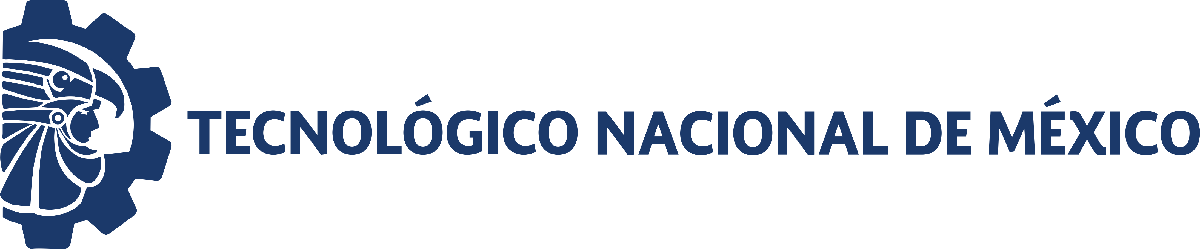                                 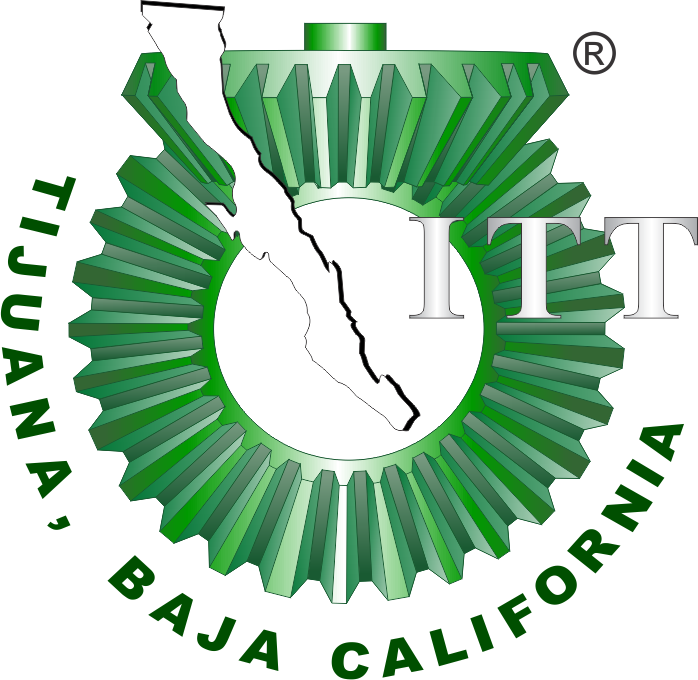

# Práctica 4: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

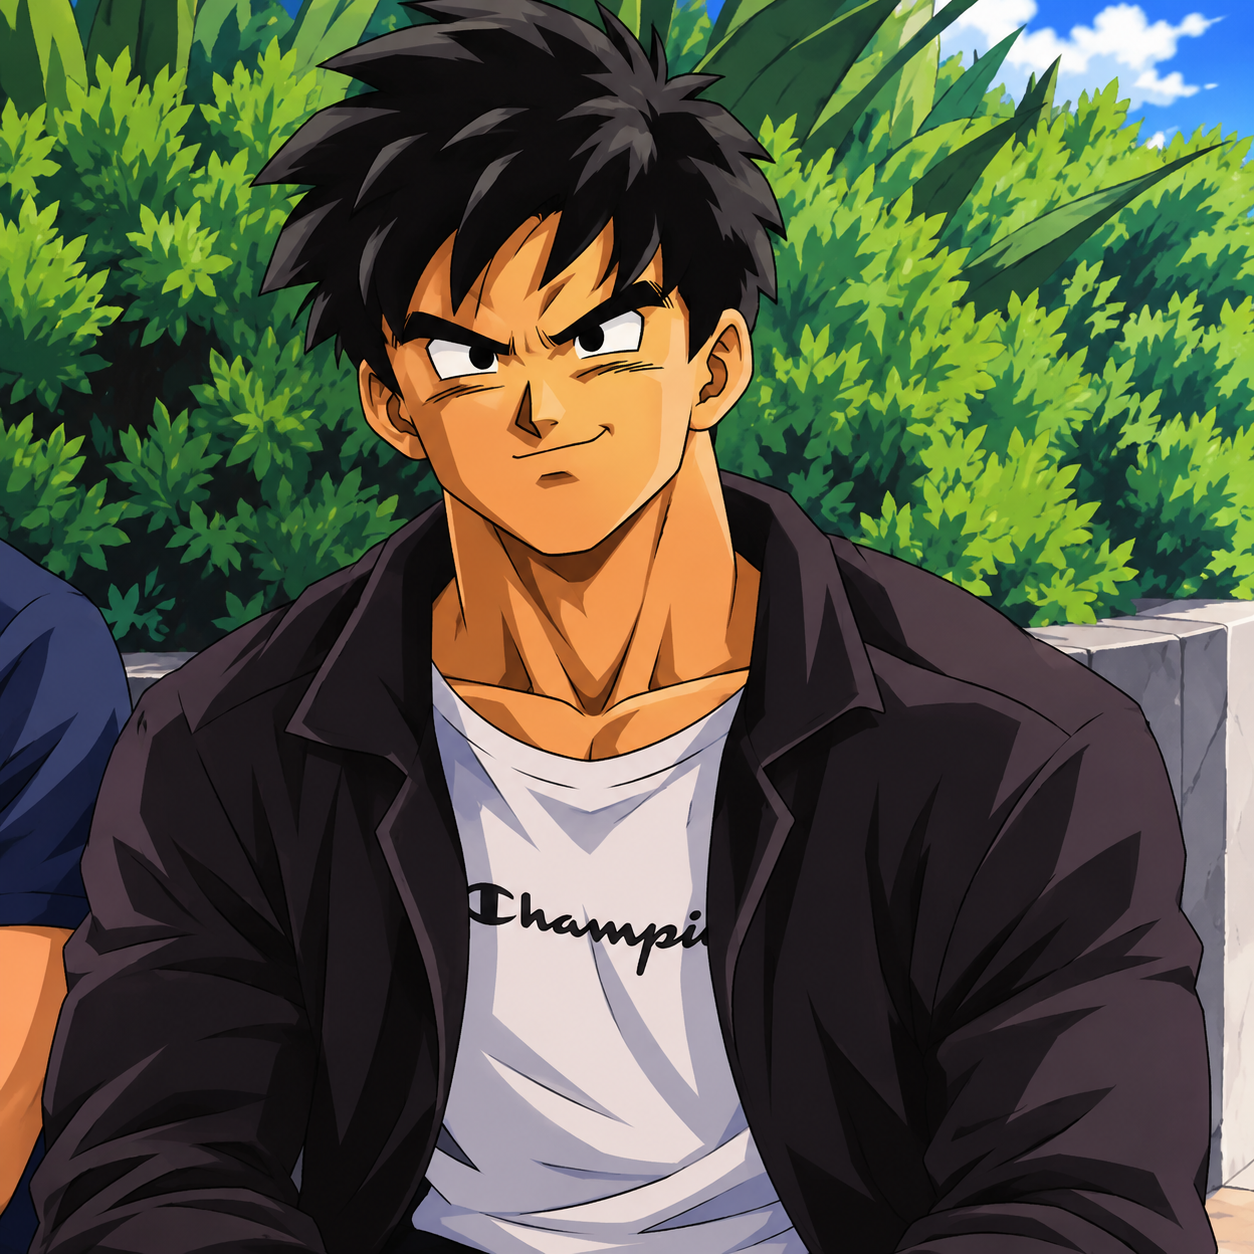

Nombre del alumno: Morales Diaz Ramon Ivan 

Número de control: 24210589

Correo institucional: l24210589**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
modelo = 'Sistemas';
open_system(modelo)
parameters.StopTime = '10';
parameters.Solver   = 'ode15s';
parameters.MaxStep  = '1e-3';
x = sim('Sistemas', parameters);

## Caso con tratamiento

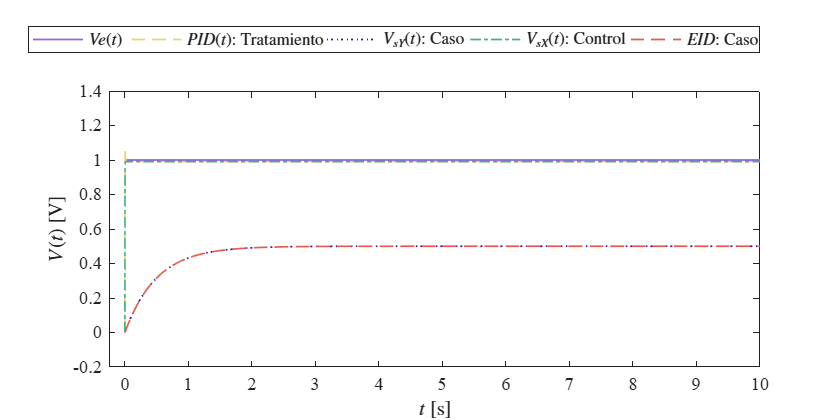

plotsignals(x.t, x.Ve, x.PID, x.Vsy, x.Vsx,x.CASO,'Caso')

## Modelo EDOs

function Vs = endocrino(par, Ve, t)
% Modelo de EDOs del sistema endócrino (circuito RLC de 2do orden)
% par = [R1 R2 L C];  Ve = entrada;  t = vector de tiempo uniforme
% Estado: x = [Vs; iL]   ->   x' = A*x + B*Ve   (Euler implícito)
R1 = par(1); R2 = par(2); L = par(3); C = par(4);
dt = t(2) - t(1);
n  = length(t) - 1;

A = [-1/(R1*C), -1/C;
    1/L,      -R2/L];
B = [1/(R1*C); 0];
M = (eye(2) - dt*A) \ eye(2);      % se calcula una sola vez

Vs = zeros(length(t), 1);          % voltaje en el nodo (salida)
il = zeros(length(t), 1);          % corriente del inductor
for i = 1:n
    z = M * ([Vs(i); il(i)] + dt*B*Ve(i+1));
    Vs(i+1) = z(1);
    il(i+1) = z(2);
end
end

function plotsignals (t,x1,x2,x3,x4,x5,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = ([149, 100, 221])/256;
clr2 = ([228, 218, 114])/256;
clr3 = ([62, 15, 141])/256;
clr4 = ([70, 180, 120]) / 256;
clr5 = ([230, 90, 80]) / 256;
order = [clr1; clr2; clr3; clr4; clr5]; colororder(order)
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$V(t)$ [V]','Interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)

if signal == "Caso"
    plot(t,x1,'-',t,x2,'--',t,x3,':',t,x4,'-.',t,x5,'--','LineWidth',1)
    L = legend('$Ve(t)$','$PID(t)$: Tratamiento','$V_{sY}(t)$: Caso','$V_{sX}(t)$: Control','$EID$: Caso');
end

set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
ylim([-0.2 1.4]); yticks(-0.2:0.2:1.4)

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end